## Read all data

First extract the data from the H5 file. 

folder = 'G:\My Drive\PRL Group\04 Projects\2 Juan\1 OPUF ANT2 CHIP02\with AuNP\';
file = 'AllDevices_Au1_Chips02_02_TM_user01.smp';

%file = 'AllDevices_Au0_Chips02_02_TM.smp';
filename = strcat(folder,file);
struct = h52struct(filename);
index1 = [16, 15, 14, 13;   % Saved Device Numbers
         1, 2 , 3, 4 ]';    % Index in the measurements list     

The follwoing data has a second user measurement of the same set of devices to carry the pairwise comaprison (intraHD)

file = 'AllDevices_Au1_Chips02_02_TM_user02.smp';

filename = strcat(folder,file);
struct2 = h52struct(filename);
index2 = [16, 15, 14, 13;   % Saved Device Numbers
         1, 2 , 3, 4 ]';    % Index in the measurements list     

Let's check the data extracted from the 1st measurement set.

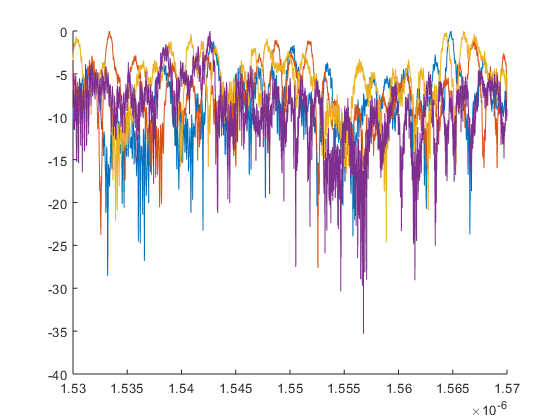

meas = struct.project.measurements;
m = meas{1}.spectra;
m(:,2) = m(:,2) - max(m(:,2));
lambda = m(:,1);

figure, clf, hold on
%all = zeros(length(m),length(meas));
all_inter = zeros(length(m),4);  

index = sortrows(index1); 
all_inter = zeros(length(m),4);

ind = 0;
for i =index(:,2)'
    ind= ind+1;
    m = meas{i}.spectra;
    m(:,2) = m(:,2) - max(m(:,2)); % Normalization
    all_inter(:,ind) = m(:,2);
    plot(m(:,1), m(:,2));
end
hold off;

Extract now the interest data from the second set of measurements.

meas = struct2.project.measurements;
m = meas{1}.spectra;
m(:,2) = m(:,2) - max(m(:,2));
lambda = m(:,1);
  
index = sortrows(index2); 
all_inter2 = zeros(length(m),4);

ind = 0;
for i =index(:,2)'
    ind= ind+1;
    m = meas{i}.spectra;
    m(:,2) = m(:,2) - max(m(:,2)); % Normalization
    all_inter2(:,ind) = m(:,2);
end

## **Statistical Analysis**

We first study the crosscorrelation of the signals, all refered to the first measurement, and create a new set of signals that are shifted in frequecy to maximaize the cross correlation with the reference one, this allows to take into account the possibility of having two difgferent devices that have simialr responses but shifted in frequency, such behviour could be derived from a very small variations of the FSR on resonant cavities that could be essentially tuned using temperature control over the chip. We limit the cross correlation test to a predifned spectral shift.  

First let's the the auto-correlation, several high peaks here would show a periodic behaviour 

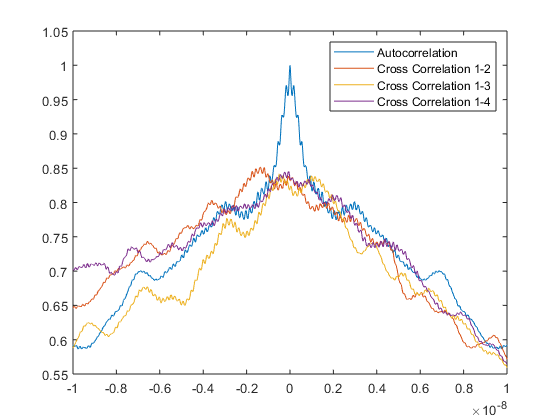

dl = lambda(2)-lambda(1);
xcorr_window = 10e-9; %in meters
xcorr_N = round(xcorr_window/dl);

[c,lags]=xcorr(all_inter(:,1),all_inter(:,1),xcorr_N,'normalized');
plot(lags/xcorr_N*xcorr_window,c);  hold on;

top_shift = 0; bot_shift = 0;
datashift = zeros(size(all_inter));  endi = length(all_inter);
datashift(:,1) = all_inter(:,1);
for i = 2:4
    [c,lags]=xcorr(all_inter(:,1),all_inter(:,i),xcorr_N,'normalized');
    plot(lags/xcorr_N*xcorr_window,c); 
    
    [v,ind]= max(c);
    shift = lags(ind);
    if shift > 0
        datashift(1+shift:endi,i) = all_inter(1:endi-shift,i);
        top_shift = max(shift,top_shift);
    else
        datashift(1:endi+shift,i) = all_inter(1-shift:endi,i);
        bot_shift = min(shift,bot_shift);
    end
end
hold off;
legend({'Autocorrelation','Cross Correlation 1-2','Cross Correlation 1-3',...
        'Cross Correlation 1-4'});


% Crop the shifted data to avoid zero values and the general data to have the same length
datashift = datashift(1+top_shift:endi,:);
c_all_u1 = all_inter(1+top_shift:endi,:);
c_lambda = lambda(1+top_shift:endi);

endi = endi-top_shift;
datashift = datashift(1:endi+bot_shift,:);
c_all_u1 = c_all_u1(1:endi+bot_shift,:);
c_lambda = c_lambda(1:endi+bot_shift);

We compute the correlation coefficients of the original samples and the shifted ones. These allows to actually test if the samples have become more 'similar' after the spectral shift. Note that although some crosscorrealtions of the shifted response are high, we should still be able to use them as PUFs as long as the following data processing takes into account higher order variations in the signal response.

A = [c_all_u1(:,1) c_all_u1(:,2) c_all_u1(:,3) c_all_u1(:,4)];
R = corrcoef(A)

R =     1.0000    0.0538    0.1516    0.0045
    0.0538    1.0000    0.1920    0.1579
    0.1516    0.1920    1.0000    0.2132
    0.0045    0.1579    0.2132    1.0000


    
A = [datashift(:,1) datashift(:,2) datashift(:,3) datashift(:,4)];
R_shift = corrcoef(A)

R_shift =     1.0000    0.3040    0.2662    0.0663
    0.3040    1.0000    0.2346    0.2216
    0.2662    0.2346    1.0000    0.2322
    0.0663    0.2216    0.2322    1.0000



all_data{1} = c_all_u1;
all_data{2} = datashift;

pair_data{1} = c_all_u1;
pair_data{2} = c_all_u2;

Undefined function or variable 'c_all_u2'.

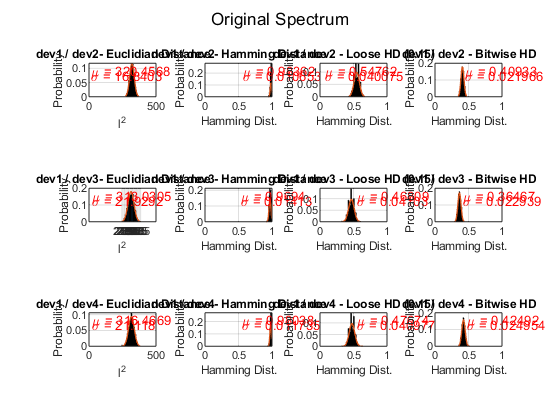

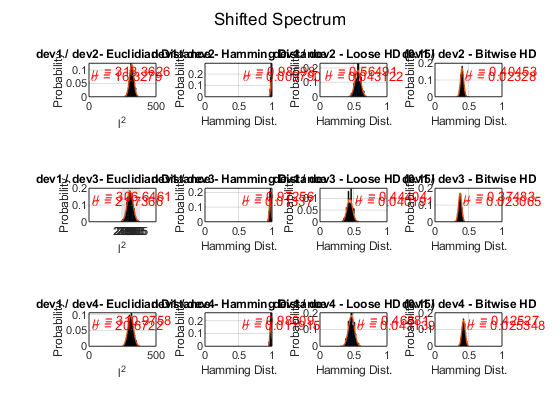

results = 1×2 cell array
    {1×3 struct}    {1×3 struct}


cmp = 1; numbits = 3; len = 3;
L = 0.15; %Looseness parameter [0.0 - 1.0]
names = {'dev1','dev2','dev3','dev4'};
titles = {'Original Spectrum','Shifted Spectrum'};
%results = HD_Compute(c_lambda, all_data, cmp, numbits, len, names,titles)

mode = 'all';
results = LHD_Compute(c_lambda, all_data, mode, L, names,titles)


mode = 'pairwise';
results = LHD_Compute(c_lambda, all_data, mode, L, names,titles)